#                                     Image processing                       

### Image reading 

I = imread("photosbill\4.jpg");

### Image before pre-processing

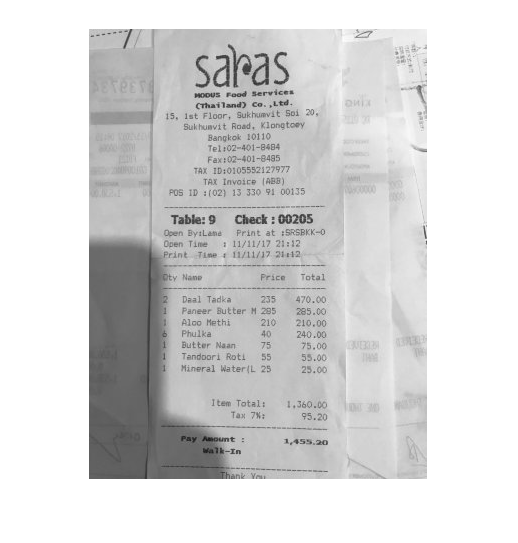

imshow(im2gray(I))

### Image pre-processing

- Gray scale imaging

- blur

- thresholding

- morphological operation

- binarize

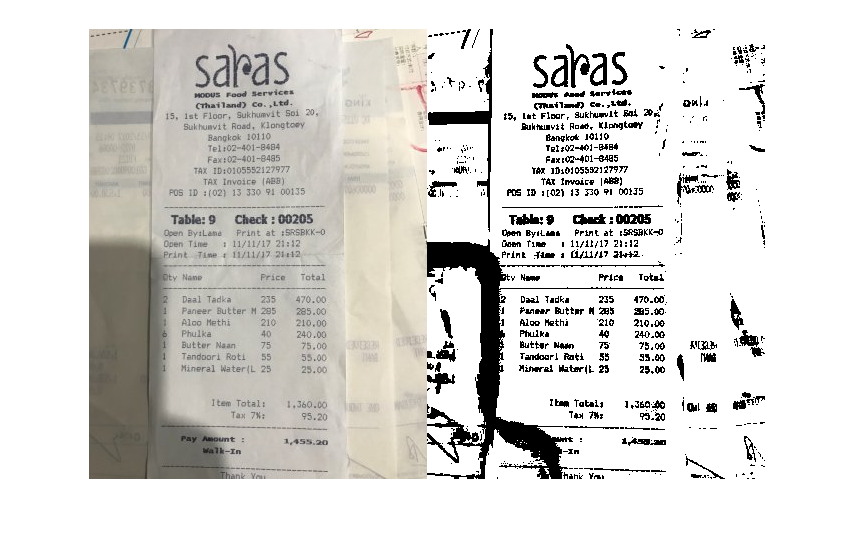

gs = im2gray(I);
gsAdj = imadjust(gs);
BW = imbinarize(gsAdj,"adaptive","ForegroundPolarity","dark");
imshowpair(I,BW,"montage")

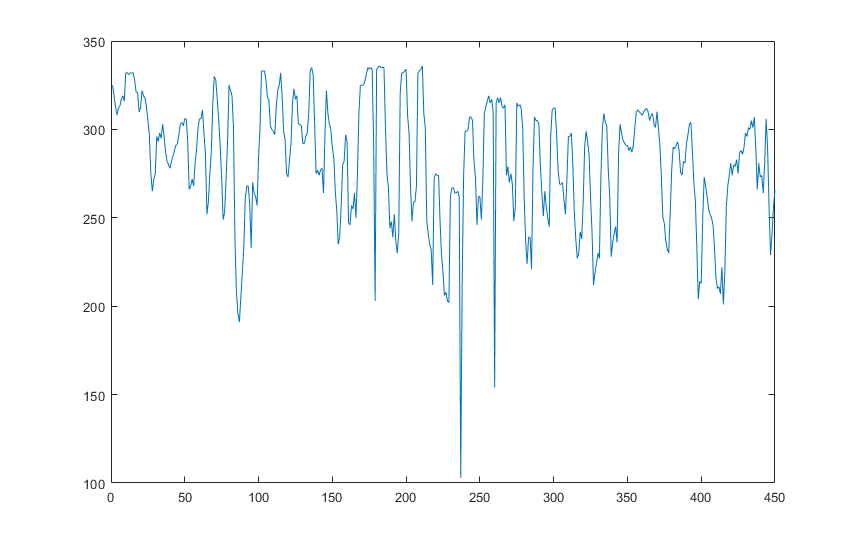

S=sum(BW,2);
plot(S);

### Optical Character Recogonition

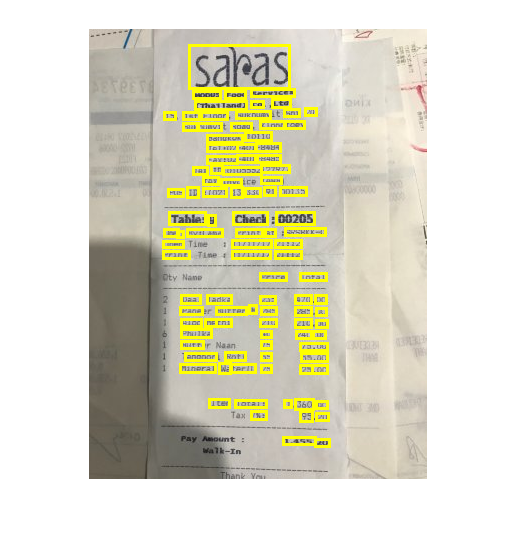

bboxes = detectTextCRAFT(I);
Iout = insertShape(I,"rectangle",bboxes,LineWidth=3);
figure
imshow(Iout)

### Extracting output

output = ocr(Iout,bboxes) 

output =   16×1 ocrText array with properties:

    Text
    CharacterBoundingBoxes
    CharacterConfidences
    Words
    WordBoundingBoxes
    WordConfidences


disp([output.Text]) 

SEIFEIS




### Storing data in csv file

csvwrite("output.csv",[output.Text])